# 7.6 Optimum filters - Kalman filter

Alexandre Rey, MSE, Ma-StatDig, 2022

clear;
rng default;

addpath('../functions/');
load_data = load('ex76_data.mat');

## Ex7.6 : Kalman filter - Truck on rail

Consider a truck on frictionless, straight rails. Initially, the truck is stationary at position 0, but it is buffeted this way and that by a random uncontrolled forces with non zero mean (trend). We measure the position of the truck every $\Delta t$ seconds, but these measurements are imprecise.

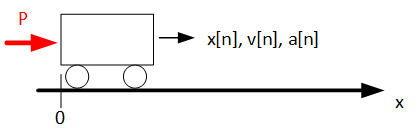

We want to maintain a model of where the truck is (position $x[n]$) and what is its velocity ($v[n]$) of a truck every $\Delta t\left\lbrack \textrm{ms}\right\rbrack$.


$$X\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{c}
x\left\lbrack n\right\rbrack \\
v\left\lbrack n\right\rbrack 
\end{array}\right\rbrack$$


The truck is pushed by a uniformely random force which creates a $\mu_a =0\ldotp 5\;\left\lbrack \frac{m}{s^2 }\right\rbrack$ mean accelaration with a standard deviation of $\sigma_a =2\;\left\lbrack \frac{m}{s^2 }\right\rbrack$. The sampling period is$100\;\left\lbrack \mathrm{ms}\right\rbrack$.

The position of the truck is measured with a high noise with a standard deviation of $\sigma_v =100\;\left\lbrack m\right\rbrack$

## Generate trajectory

### Parameters

Based on the description, the following parameters are defined:

dt = 100e-3;            % [s]
AccelerationMean = 0.5; % [m/s^2]
SigmaA = 2;             % standard deviation
SigmaV = 100;           % standard deviation
N = 1000;
n = 0:N-1;

disp(table(dt, AccelerationMean, SigmaA, SigmaV, N));

    dt     AccelerationMean    SigmaA    SigmaV     N  
    ___    ________________    ______    ______    ____

    0.1          0.5             2        100      1000



### Generation

We can write the motion equations:


$$\left\lbrace \begin{array}{ll}
x\left\lbrack n\right\rbrack  & =x\left\lbrack n-1\right\rbrack +v\left\lbrack n-1\right\rbrack \cdot \Delta t+\frac{1}{2}{\left(\Delta t\right)}^2 a\left\lbrack n-1\right\rbrack \\
v\left\lbrack n\right\rbrack  & =v\left\lbrack n-1\right\rbrack +\Delta t\cdot a\left\lbrack n-1\right\rbrack 
\end{array}\right.$$


They can be written in matrix shape:


$$\left\lbrack \begin{array}{c}
x\left\lbrack n\right\rbrack \\
v\left\lbrack n\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & \Delta t\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left\lbrack n-1\right\rbrack \\
v\left\lbrack n-1\right\rbrack 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{1}{2}\Delta t^2 \\
\Delta t
\end{array}\right\rbrack a\left\lbrack n-1\right\rbrack$$


or in compact shape:


$$\mathit{\mathbf{X}}\left\lbrack n\right\rbrack =\mathit{\mathbf{F}}\cdot \mathit{\mathbf{X}}\left\lbrack n-1\right\rbrack +\mathit{\mathbf{B}}\cdot a\left\lbrack n-1\right\rbrack \;$$


where a[n] is a uniformy distributed noise with non nul mean $\mu_a$ and variance of $\sigma_a$.

And the only the position of the truck is measured.


$$z\left\lbrack n\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left\lbrack n\right\rbrack \\
v\left\lbrack n\right\rbrack 
\end{array}\right\rbrack +\mathrm{vn}\left\lbrack n\right\rbrack$$


Attention : $v_n$ est un bruit sur la position donc sur $x[n]$

Or in compact shape:


$$z\left\lbrack n\right\rbrack =\mathit{\mathbf{H}}\cdot \;\mathit{\mathbf{X}}\left\lbrack n\right\rbrack +\textrm{vn}\left\lbrack n\right\rbrack$$


Where $\textrm{vn}$[n] is the measurement noise which is normally distributed with zero mean and a variance of $\sigma_v^2$.

F = [1, dt; 0, 1];
B = [0.5*dt^2; dt];
H = [1 0];

disp('F='); disp(F); disp('B='); disp(B); disp('H='); disp(H);

F=
    1.0000    0.1000
         0    1.0000

B=
    0.0050
    0.1000

H=
     1     0



### Generation

Based on the previous equations, the truck position is generated.

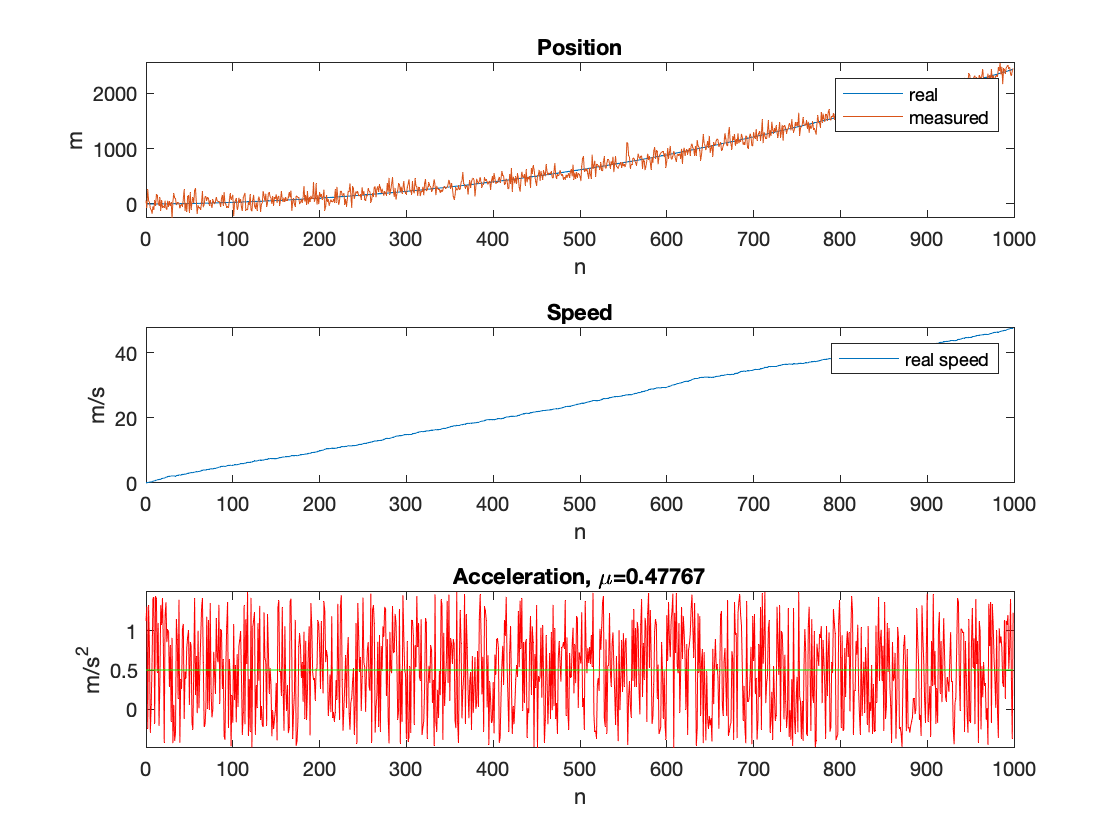

% load_data.a est l'accélération réelle
% load_data.vn est la position mesurée
xHat0 = [0;0]; % distance et vitesse nulle
X = zeros(length(xHat0),N);
X(:,1) = xHat0;
for k=2:N
    X(:,k) = F*X(:,k-1) + B.*load_data.a(:,k);
end
% theorical position + speed
X = table(X(1,:)',X(2,:)');
X.Properties.VariableNames = ["x","v"];

% measured position
Z = H*X{:,:}' + load_data.vn;

figure
tiledlayout(3,1)
ax1 = nexttile;
    plot(n, X.x, ...
         n, Z)
    title('Position')
    legend('real', 'measured')
    xlabel('n')
    ylabel('m')
ax2 = nexttile;
    plot(n, X.v)
    title('Speed')
    legend('real speed');
    xlabel('n')
    ylabel('m/s')
ax3 = nexttile;
    plot(n, load_data.a, 'r', ...
         n, AccelerationMean*ones(1,N), 'g')
    mu=mean(load_data.a, "all");
    title(['Acceleration, \mu=', num2str(mu)])
    xlabel('n')
    ylabel('m/s^2')
linkaxes([ax1,ax2], 'x');

    clear mu;

## Kalman Filter

### Kalman matrices

The previous already defined the matrices **F**, **B**, and **H**.

Only the covariance matrix for the process noise and the measurement are missing. The covariance matrix of the process is :


$${\mathit{\mathbf{Q}}}_w =\mathit{\mathbf{G}}\cdot {\mathit{\mathbf{G}}}^T \sigma_a^2$$


Where G is the input-model for the unknown input. For this example, the matrix **G** is equal to **B**.

Finally, the covariance matrix of the measurement noise is:


$${\mathit{\mathbf{Q}}}_v =\sigma_v^2$$


Qw = B*B'.*SigmaA^2;
Qv = SigmaV^2;

disp('Qw='); disp(Qw); disp('Qv='); disp(Qv)

Qw=
    0.0001    0.0020
    0.0020    0.0400

Qv=
       10000



### Inital condition

And the initial conditions are defined as null as the truck is at a known position.


$$\hat{\mathit{\mathbf{X}}} \left\lbrack 0|0\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$



$$P\left\lbrack 0|0\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0
\end{array}\right\rbrack$$


P0 = [0 0; 0 0];
disp('Xhat0='); disp(xHat0); disp('PInit='); disp(P0);

Xhat0=
     0
     0

PInit=
     0     0
     0     0



### Apply Kalman filter

Finally, the kalman filter can be applied. It gives the following estimation. The $u$ input vector is simply a constant with the average mean value of the input acceleration.

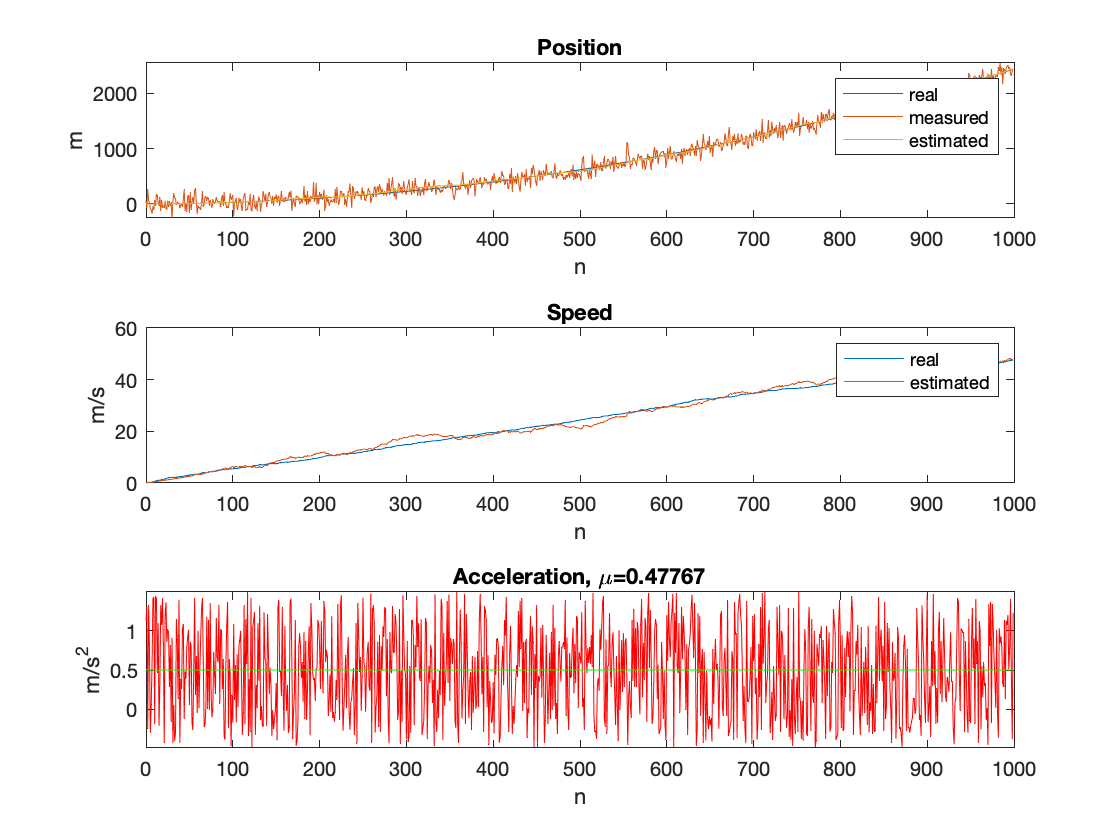

[K, xHat, P] = kalmanGain(F, H, Qw, Qv, xHat0, P0, Z, B, AccelerationMean*ones(1,N));

xHat = table(xHat(1,:)', xHat(2,:)');
xHat.Properties.VariableNames = ["x","v"];

figure
tiledlayout(3,1)
nexttile;
    plot(n, X.x, ...
         n, Z, ...
         n, xHat.x)
    title('Position')
    legend('real', 'measured', 'estimated')
    xlabel('n')
    ylabel('m')
nexttile;
    plot(n, X.v, ...
         n, xHat.v)
    title('Speed')
    legend('real', 'estimated')
    xlabel('n')
    ylabel('m/s')
nexttile;
    plot(n, load_data.a, 'r', ...
         n, AccelerationMean*ones(1,N), 'g')
    mu=mean(load_data.a, "all");
    title(['Acceleration, \mu=', num2str(mu)])
    xlabel('n')
    ylabel('m/s^2')

The Kalman gain and the estimated errors accross time can be also shown.

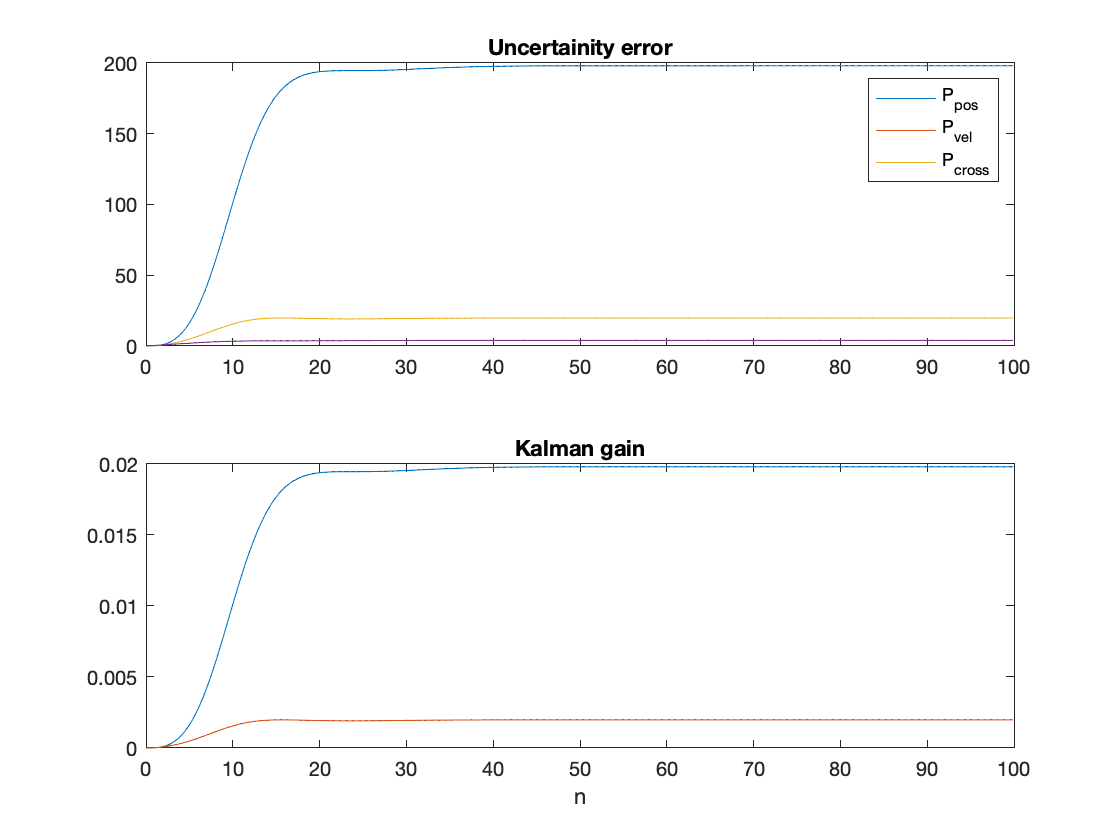

figure
tiledlayout(2,1)
ax1 = nexttile;
    plot(n*dt, reshape(P, [4, N]))
    title('Uncertainity error')
    legend('P_{pos}','P_{vel}','P_{cross}')
ax2 = nexttile;
    plot(n*dt, squeeze(K)')
    title('Kalman gain')
    xlabel('n')